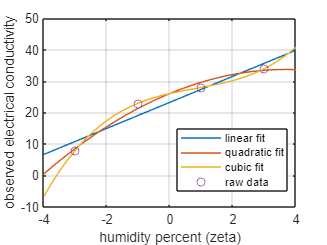

% raw data and preprocessing
x = [20, 30, 40, 50];
x = (x - 35) ./ 5;

b = [8, 23, 28, 34];

% linear fit
A_l = cat(2, ones(1, 4)', x');
xls_l = inv(A_l'*A_l) * A_l'*b';

% quadratic fit
A_q = cat(2, ones(1, 4)', x', x'.^2);
xls_q = inv(A_q'*A_q) * A_q'*b';

% cubic fit
A_c = cat(2, ones(1, 4)', x', x'.^2, x'.^3);
xls_c = inv(A_c'*A_c) * A_c'*b';

% plotting
x_vals = linspace(-4, 4);
plot(x_vals, xls_l(1) + xls_l(2)*x_vals);
hold on;
plot(x_vals, xls_q(1) + xls_q(2)*x_vals + xls_q(3)*x_vals.^2);
hold on;
plot(x_vals, xls_c(1) + xls_c(2)*x_vals + xls_c(3)*x_vals.^2 + xls_c(4)*x_vals.^3);
hold on;
plot(x, b, "-o", LineStyle="none");

legend("linear fit", "quadratic fit", "cubic fit", "raw data", location="best");
xlabel("humidity percent (zeta)");
ylabel("observed electrical conductivity");
grid on;